## Display the original image on screen.

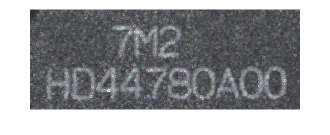

clc; clear;
img = imread('charact2.bmp');
imshow(img);

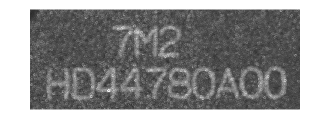

% Convert the Image to Grayscale
grayImg = rgb2gray(img);
imshow(grayImg);

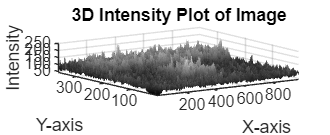

% Create a 3D plot of the grayscale image
create3DIntensityPlot(grayImg)

## Implement a 3x3 Averaging Mask

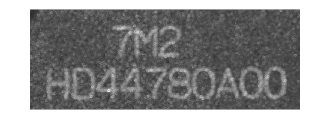

% Create a 3x3 averaging filter
avgFilter = ones(3, 3) / 9;
% Apply the averaging filter to the image
avgFilteredImg = imfilter(grayImg, avgFilter);
% Show the avg filter image
imshow(avgFilteredImg);

## Implementing a 3x3 Rotating Mask

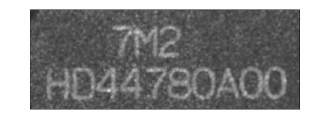

rotFilter = [8 1 1; 1 1 1; 1 1 1];
rotFilter = rotFilter ./ sum(rotFilter(:));
rotFilteredImg = avgFilteredImg;

for i = 1:4
    rotFilteredImg = imfilter(rotFilteredImg, rotFilter);
    rotFilter = rot90(rotFilter);
end
imshow(rotFilteredImg);

## Gaussian Filtering

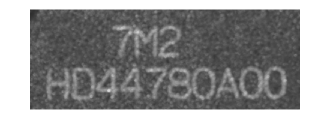

gaussFilteredImg = imgaussfilt(grayImg, 2);
imshow(gaussFilteredImg);

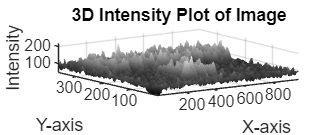

create3DIntensityPlot(gaussFilteredImg);

## Sobel operation

% SobelMagnitude = applySobel(gaussFilteredImg);
% imshow(SobelMagnitude);
% create3DIntensityPlot(SobelMagnitude);

## Experiment with masks of different sizes

## Morphological Operation

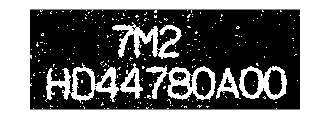

% Process the image to extract "HD44780A00", find outlines and segment characters
thresholdValue = graythresh(avgFilteredImg);
binaryImg = imbinarize(avgFilteredImg, thresholdValue);
imshow(binaryImg);

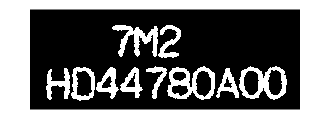

morphProcessedImg = applyMorphologicalProcessing(binaryImg);
imshow(morphProcessedImg);

## Extract Sub-Image

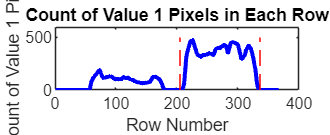

% extract sub-image
counts = sum(morphProcessedImg, 2);
threshold = 250;
startOfCharacters = find(counts > threshold, 1, 'first') - 10;
endOfCharacters = find(counts > threshold, 1, 'last') + 10;
plot(counts, 'b', 'LineWidth', 2);
title('Count of Value 1 Pixels in Each Row');
xlabel('Row Number');
ylabel('Count of Value 1 Pixels');
ylim = get(gca, 'YLim'); % Get the current y-axis limits
line([startOfCharacters startOfCharacters], ylim, 'Color', 'r', 'LineStyle', '--');
line([endOfCharacters endOfCharacters], ylim, 'Color', 'r', 'LineStyle', '--');

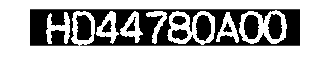

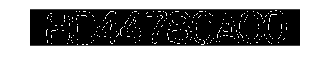

charLabels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

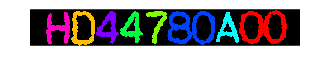

lowerImg = morphProcessedImg(startOfCharacters:endOfCharacters, :);
imshow(lowerImg);

## Segment Characters

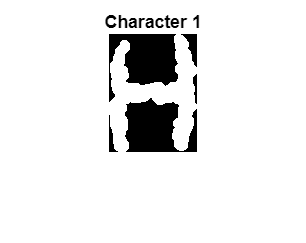

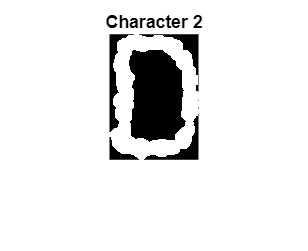

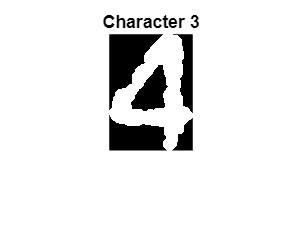

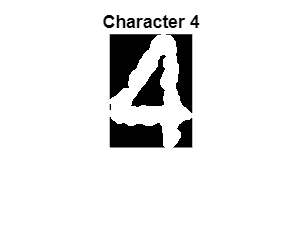

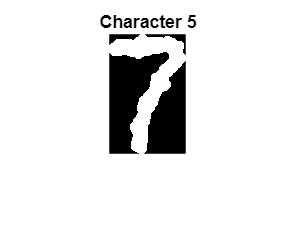

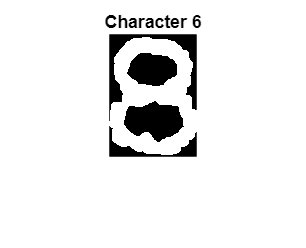

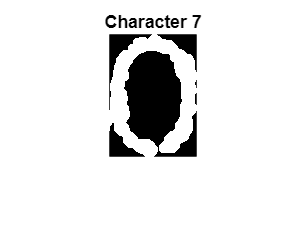

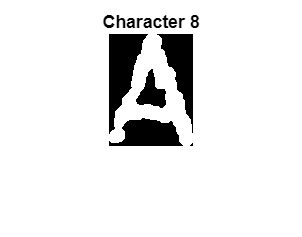

% Define the directory to save character images
outputDir = '.\Characters';  % Change this to your desired path
if ~exist(outputDir, 'dir')
    mkdir(outputDir);  % If the directory doesn't exist, create it
end

% Segment characters
% Label connected components
[charLabels, charNum] = bwlabel(lowerImg);

% Loop through each label to extract, display, and save character images
charIdx = 1;
for n = 1:charNum
    % Find the boundaries of the nth character
    [row, col] = find(charLabels == n);
    
    % Determine the bounding box around the character
    topRow = min(row);
    bottomRow = max(row);
    leftColumn = min(col);
    rightColumn = max(col);
    
    % Cut the character out of the image
    characterImg = lowerImg(topRow:bottomRow, leftColumn:rightColumn);

    if (n == 6) || (n == 8)
        [height, width] = size(characterImg);
        midPoint = round(width / 2);
        % Crop the left and right halves
        leftHalf = characterImg(:, 1:midPoint);
        rightHalf = characterImg(:, midPoint+1:end);
        imwrite(leftHalf, fullfile(outputDir, sprintf('Character_%d.png', charIdx)));
        figure;
        imshow(leftHalf);
        title(['Character ', num2str(charIdx)]);
        charIdx = charIdx + 1;
        imwrite(rightHalf, fullfile(outputDir, sprintf('Character_%d.png', charIdx)));
        figure;
        imshow(rightHalf);
        title(['Character ', num2str(charIdx)]);
        charIdx = charIdx + 1;
        continue;
    end
    
    % Save the character image as a PNG file in the output directory
    imwrite(characterImg, sprintf('Character_%d.png', charIdx));
    
    % Optionally display each character with a figure
    figure;
    imshow(characterImg);
    title(['Character ', num2str(charIdx)]);
    charIdx = charIdx + 1;
end

## Find edges and segment characters

% Find edges and segment characters
charEdges = edge(lowerImg, 'canny'); % Detect edges
imshow(charEdges);

[charLabels, ~] = bwlabel(lowerImg) % Label connected components

charLabels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

coloredLabels = label2rgb(charLabels, 'hsv', 'k', 'shuffle'); % Color labels for visualization
imshow(coloredLabels);

## Functions

### create3DIntensityPlot

function create3DIntensityPlot(img)
    % Check if the image is grayscale; if not, convert it
    if size(img, 3) == 3
        img = rgb2gray(img);
    end

    % Create a 3D plot of the grayscale image
    [X, Y] = meshgrid(1:size(img, 2), 1:size(img, 1));
    Z = double(img);
    surf(X, Y, Z, 'EdgeColor', 'none');
    colormap('gray'), axis tight, view(-35, 45);
    xlabel('X-axis'), ylabel('Y-axis'), zlabel('Intensity');
    title('3D Intensity Plot of Image');
end

### sobel operation

function sobelMagnitude = applySobel(img)
    % Sobel filter for horizontal and vertical edge detection
    Gx = [-1 0 1; -2 0 2; -1 0 1];
    Gy = [-1 -2 -1; 0 0 0; 1 2 1];
    % Apply the horizontal Sobel filters
    grad_x = imfilter(double(img), Gx, 'same', 'replicate');
    % Apply the vertical Sobel filters
    grad_y = imfilter(double(img), Gy, 'same', 'replicate');
    % Display both gradients
    % subplot(1, 2, 1), imshow(grad_x), title('Horizontal Edges (Sobel - Gx)');
    % subplot(1, 2, 2), imshow(grad_y), title('Vertical Edges (Sobel - Gy)');
    % Calculate the magnitude of the gradient
    sobelMagnitude = sqrt(grad_x.^2 + grad_y.^2);
    sobelMagnitude = mat2gray(sobelMagnitude);
end

### morphological operation

function morphProcessedImg = applyMorphologicalProcessing(binaryImg)
    % Create structuring element
    se = strel('disk', 5);
    binaryImg = imopen(binaryImg, se);
    binaryImg = bwareaopen(binaryImg, 200);
    morphProcessedImg = binaryImg;
end